# graph_SP.mlx

`../output/kob_test_36sec_2.csv`の図示

SP

`graph.m`は内容同じ

clear;
close all;

df = readtable('../output/kob_test_36sec_SP.csv');
head(df)

ans = 8×14 table
         time            day        short_radi    salinity_wc    salinity_pw     tide        psi_wc         psi_pw       Jv_upward        Pg            R        DIC_sav    DIN_sav    DO_sav
    ______________    __________    __________    ___________    ___________    _______    ___________    ___________    __________    _________    _________    _______    _______    ______

    {'0D09:59:59'}             0      831.85         34.99         33.498       0.59918    -2.4818e+06    -2.3726e+06    7.2831e-05    0.0028787    0.0010909    1999.9     14.995      4.066
    {'0D10:00:35'}    0.00041667      833.35        34.987         33.497       0.59893    -2.4816e+06    -2.3725e+06     7.271e-05     0.002881    0.0010987    1999.9      14.99     4.1318
    {'0D10:01:11'}    0.00083333      834.85        34.984         33.497       0.59868    -2.4814e+06    -2.3725e+06     7.259e-05    0.0028834    0.0011064    1999.8     14.986     4.1974
    {'0D10:01:47'}       0.00125

height(df)

ans = 16801

row_count = transpose(1:1:height(df));
newNames = "row_count";
df = addvars(df,row_count,'NewvariableNames',newNames)

df = 16801×15 table
         time            day        short_radi    salinity_wc    salinity_pw     tide        psi_wc         psi_pw       Jv_upward        Pg            R        DIC_sav    DIN_sav    DO_sav    row_count
    ______________    __________    __________    ___________    ___________    _______    ___________    ___________    __________    _________    _________    _______    _______    ______    _________

    {'0D09:59:59'}             0      831.85         34.99         33.498       0.59918    -2.4818e+06    -2.3726e+06    7.2831e-05    0.0028787    0.0010909    1999.9     14.995      4.066        1    
    {'0D10:00:35'}    0.00041667      833.35        34.987         33.497       0.59893    -2.4816e+06    -2.3725e+06     7.271e-05     0.002881    0.0010987    1999.9      14.99     4.1318        2    
    {'0D10:01:11'}    0.00083333      834.85        34.984         33.497       0.59868    -2.4814e+06    -2.3725e+06     7.259e-05    0.0028834    0.0011064    1999.8

% df.hour = df.t_min / 60;
df.psi_wc = df.psi_wc / 1000000;
df.psi_pw = df.psi_pw / 1000000;

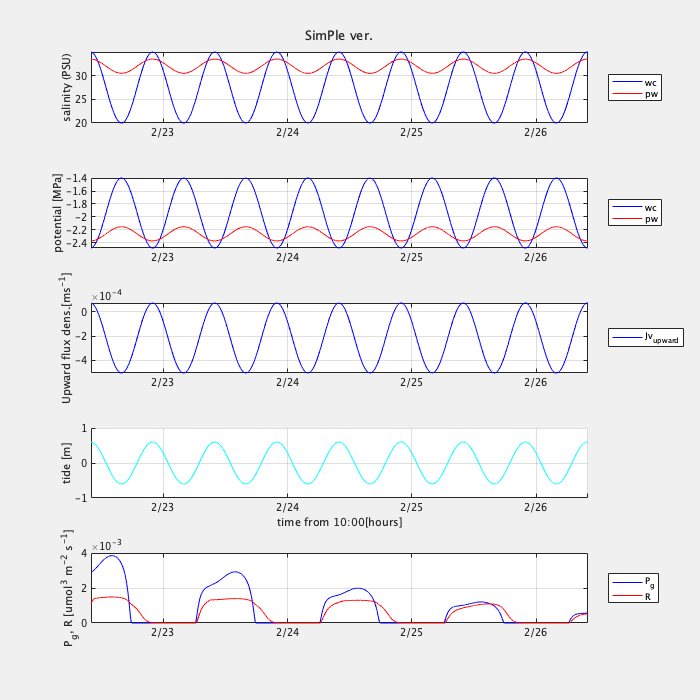

figure('visible','on','Position',[100 100 700 700]);
tiledlayout(5,1)

sgtitle('SimPle ver.');

% xl = [1 height(df)];
% xticks_num = [1 301 601 901 1201 1501 1801 2101 2401];
% xticks_hourname = {'10:00','13:00','16:00','19:00','22:00','1:00','4:00','7:00','10:00'};

% % for 4 days
xl = [1 9601];
xticks_num = [1 1401 3801 6201 8601 9601];
xticks_hourname = {' ','2/23','2/24','2/25','2/26', ' '};

%subplot(4,1,1)
ax1 = nexttile;
x  = df.row_count;
y1 = df.salinity_wc;
y2 = df.salinity_pw;
plot(x,y1,'b',x,y2,'r')
% clear ylim
xlim(xl);
% ylim([33 38]);
xticks(xticks_num);
xticklabels(xticks_hourname);
% yticks([33 34 35 36 37 38]);
ylabel('salinity (PSU)');
legend('wc','pw','Location',"eastoutside");
grid on;

%subplot(4,1,2)
ax2 = nexttile;
y4 = df.psi_wc;
y5 = df.psi_pw;

plot(x,y4,'b',x,y5,'r')
xlim(xl);
% ylim([-2.7 -2.3]);
xticks(xticks_num);
xticklabels(xticks_hourname);
% yticks([-2.7 -2.6 -2.5 -2.4 -2.3]);
ylabel('potential [MPa]');
legend('wc','pw','Location',"eastoutside");
grid on;

%subplot(4,1,3)
ax3 = nexttile;
y8 = df.Jv_upward;
plot(x,y8,'b')
xlim(xl);
% ylim([0.2 0.6]);
xticks(xticks_num);
xticklabels(xticks_hourname);
% yticks([0.2 0.3 0.4 0.5 0.6]);
% clear xticklabels
% xticklabels({});
ylabel('Upward flux dens.[ms^{-1}]');
legend('Jv_{upward}','Location',"eastoutside");
grid on;

% subplot(4,1,4)
ax4 = nexttile;
y10 = df.tide;
hold on
plot(x,y10,'Color','c','Marker','none')
clear ylim
ylim([-1 1])
% yticks([-1 0 1]);
ylabel('tide [m]');

xlim(xl);
xticks(xticks_num);
xticklabels(xticks_hourname);
xlabel('time from 10:00[hours]');
grid on
hold off

ax5 = nexttile;
y12 = df.Pg;
y13 = df.R;
plot(x,y12,'b-',x,y13,'r-')
xlim(xl);
% ylim([0.2 0.6]);
xticks(xticks_num);
xticklabels(xticks_hourname);
% yticks([0.2 0.3 0.4 0.5 0.6]);
% clear xticklabels
% xticklabels({});
ylabel('P_g, R [umol^3 m^{-2} s^{-1}]');
legend('P_g','R','Location',"eastoutside");
grid on;
xlim(xl);
xticks(xticks_num);
xticklabels(xticks_hourname);
% xlabel('date (10:00)');


linkaxes([ax1,ax2,ax3,ax4,ax5],'x');